# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 8-b. 위상 뒤짐 보상기 설계**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr)

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 기본 설정

다음의 연속 시간 시스템 $G_p(s)$로 구성된 샘플 데이터 시스템을 생각해봅시다. 


$$G_p(s) = \frac{15}{s^2 + 2s + 2}$$


num_Gp_tf = 15;
den_Gp_tf = [1 2 2];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);
T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh');

위의 이산 시간 시스템의 이득/위상 여유는 다음과 같이 계산됩니다. 

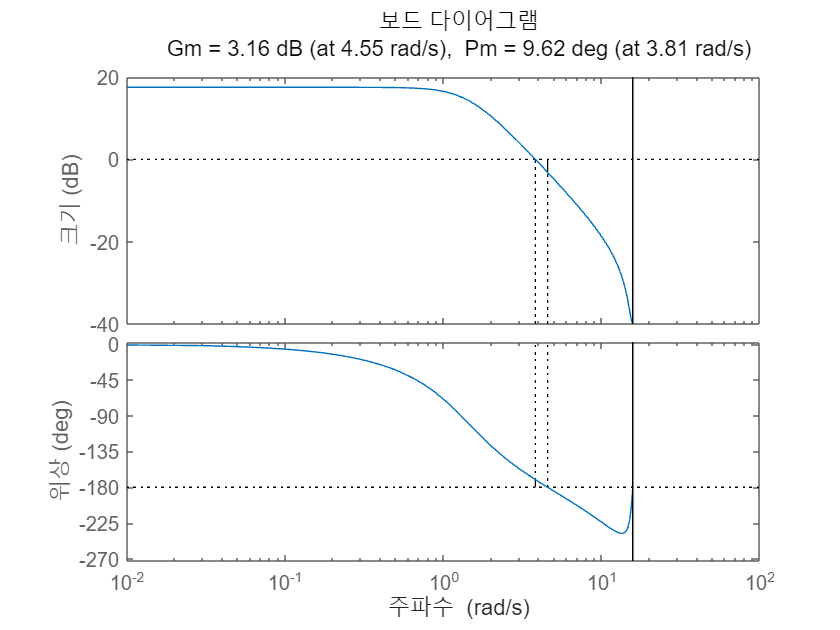

margin(Gd_tf)

nyquist(Gd_tf)

이번 실습에서는 위의 시스템의 이득/위상 여유를 추가로 확보하기 위한 이산 시간 1차 보상기


$$D^d(z) = K_C\frac{z-z_0}{z-z_p}$$


를 설계합니다. 

원래는 $z$-영역에서 위상 뒤짐/앞섬 보상기를 직접 설계하는 것이 더 이상적이지만, 지금은 교재에서처럼 쌍선형 변환(bilinear transformation)을 이용하여 변환된 ${\rm w}$-영역에서의 1차 보상기 


$$D^{\rm w}({\rm w}) = D^d(z)\bigg|_{z = \frac{1 + (T/2) {\rm w}}{1 - (T/2){\rm w}}} = a_0 \frac{1 + {\rm w}/\omega_{\rm w0}}{1 + {\rm w}/\omega_{\rm wp}}$$


을 먼저 설계한 뒤, 이를 역변환하는 방식으로 진행합니다. 

만약 $a_0$, $\omega_{\rm wp}$, $\omega_{\rm w 0}$ 등이 결정되었다면, 이산 시간 1차 보상기의 설계 변수들은 다음과 같이 자동으로 결정됩니다. 

- 
$$	K_{\rm C} = a_0 \left( \frac{\omega_{\rm wp} (\omega_{\rm w0} + 2/T)}{\omega_{\rm w0} (\omega_{\rm wp} + 2/T)} \right)$$


- $z_0 = \frac{2/T - \omega_{\rm w0}}{2/T + \omega_{\rm w0}}$,

- 
$$z_{\rm p} = \frac{2/T - \omega_{\rm wp}}{2/T + \omega_{\rm wp}}$$


(이번 파일에서는 위상 뒤짐 보상기만 설계하도록 하겠습니다.)

### Topic 2 : 위상 뒤짐(phase lag) 보상기 설계

Topic 2에서는 1차 보상기의 형태로 설계되는 위상 뒤짐 보상기 $D_{\rm lag}^d(z)$를 설계하고자 합니다.

설계를 위해 우선 펄스 전달함수 $G^d(z)$를 쌍선형 변환하여 $G^{\rm w}({\rm w})$를 얻습니다. 

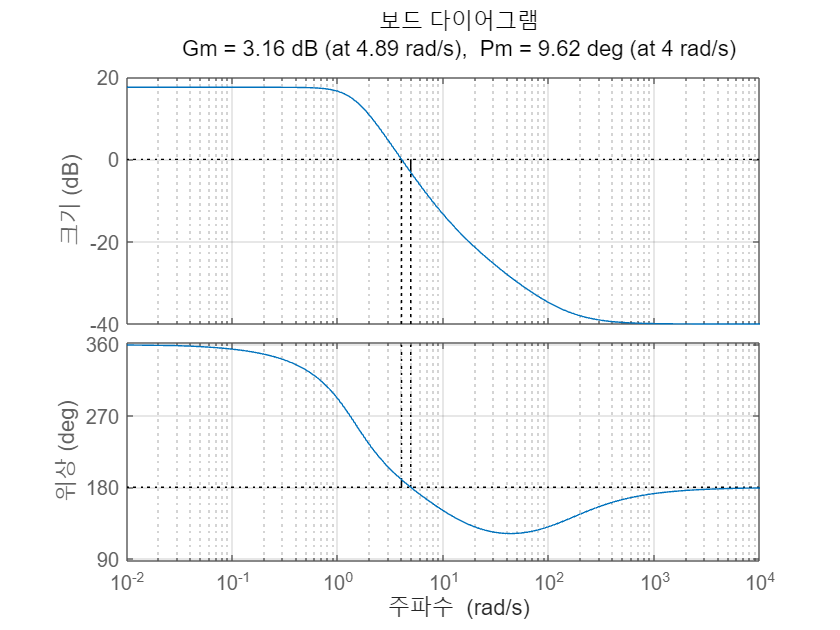

Gw_tf = d2c(Gd_tf, 'tustin');
figure();
margin(Gw_tf); grid on;

현재 위상 여유는 약 10 degree인데, 이를 25 degree 이상으로 확보하는 것을 목표로 합시다. 

(즉, 목표하는 위상 여유 $\phi_m = 25 ^\circ$라고 합시다.)

**[Step 1] **먼저 $\angle G^{\rm w}(j\omega_{\rm w 1})\approx -180^\circ + \phi_m + 5^\circ =-150^\circ$이 되는 $\omega_{\rm w1}$를 찾습니다. 

위의 보데 위상 선도가 $360^\circ$를 기준으로 작성되어 있기 때문에, $-150^\circ$와 결과적으로 동일한 $360^\circ - 150^\circ = 210^\circ$에 해당하는 $2.75~{\rm rad/s}$를 $\omega_{\rm w1}$으로 합시다.

omega_w1 = 2.75;

**[Step 2] **$\omega_{\rm w0} < 0.1\omega_{\rm w1}$으로 합시다. 

omega_w0 = 0.002 * omega_w1

omega_w0 = 0.0055

**[Step 3] **$\omega_{wp} \leq \frac{\omega_{w0}}{a_0 |G^{\rm w}(j\omega_{w1})|}$로 선정합시다. (교재 상의 가이드라인에서는 등호로 표시되어 있지만, 실제로는 그보다는 더 작은 값으로 선정해야 원하는 여유 값을 얻을 수 있습니다.)

$a_0$는 임의로 $1.2$로 선정하였으며, $|G^{\rm w}(j\omega_{\rm w1})|$은 보데 선도를 통해 약 $5.96~{\rm dB} = {\rm exp}(5.96/20) \approx 1.3472$로 확인할 수 있습니다.

이를 이용하여 적당한 튜닝을 통해 다음을 얻었습니다. 

a0 = 1.2;
omega_wp = omega_w0/a0/2

omega_wp = 0.0023

이제 $D^{\rm w}({\rm w}) = D^d(z)\bigg|_{z = \frac{1 + (T/2) {\rm w}}{1 - (T/2){\rm w}}} = a_0 \frac{1 + {\rm w}/\omega_{\rm w0}}{1 + {\rm w}/\omega_{\rm wp}}$를 다음과 같이 얻습니다.

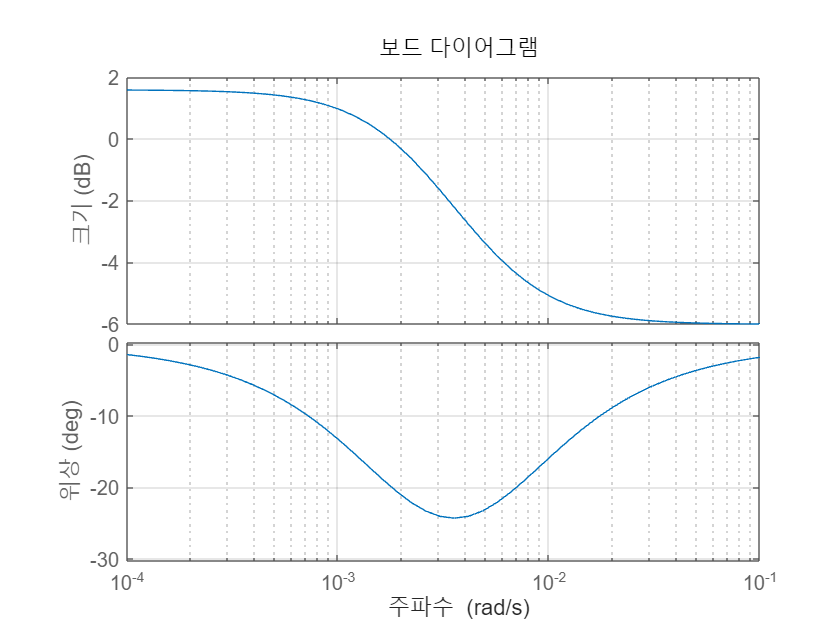

Dw_lag_tf = a0 * tf([1/omega_w0 1], [1/omega_wp 1]);
figure();
bode(Dw_lag_tf); grid on;

이제 ${\rm w}$-영역에서 위상 뒤짐 제어기를 적용하기 전과 적용한 이후의 보데 선도를 겹쳐서 그리면 다음을 얻습니다. 

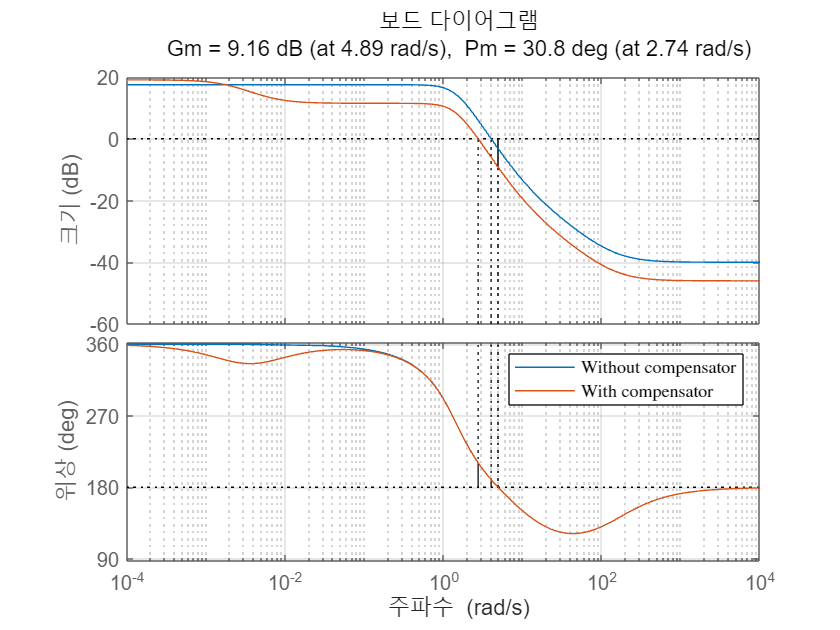

figure();
margin(Gw_tf); hold on;
margin(Gw_tf * Dw_lag_tf); grid on;
legend('Without compensator', 'With compensator', 'Interpreter', ' latex');

기존 개루프 전달함수와 비교하여, 보상기가 적용된 새로운 개루프 전달함수는 위상 뒤짐 제어기 덕분에 교차주파수(crossover frequency) 주변에서의 크기가 약 $-6~{\rm dB}$만큼 작아졌습니다. 

이 덕분에 위상 교차주파수가 좀 더 앞당겨지면서, 추가적인 위상 이득을 얻게 됩니다. 

실제로 `margin` 함수로부터 계산해보면, 처음 기대했던 값인 $25^\circ$ 이상의 위상 여유를 얻게되었음을 확인할 수 있습니다.

[Gm_lag,Pm_lag,Wcg_lag,Wcp_lag] = margin(Gw_tf * Dw_lag_tf)

Gm_lag = 2.8720

Pm_lag = 30.7817

Wcg_lag = 4.8862

Wcp_lag = 2.7365

쌍선형 변환의 특징으로 인해, $z$-영역으로 변환한 후 다시 보데 선도를 그려봐도 동일한 결론을 얻을 수 있습니다.

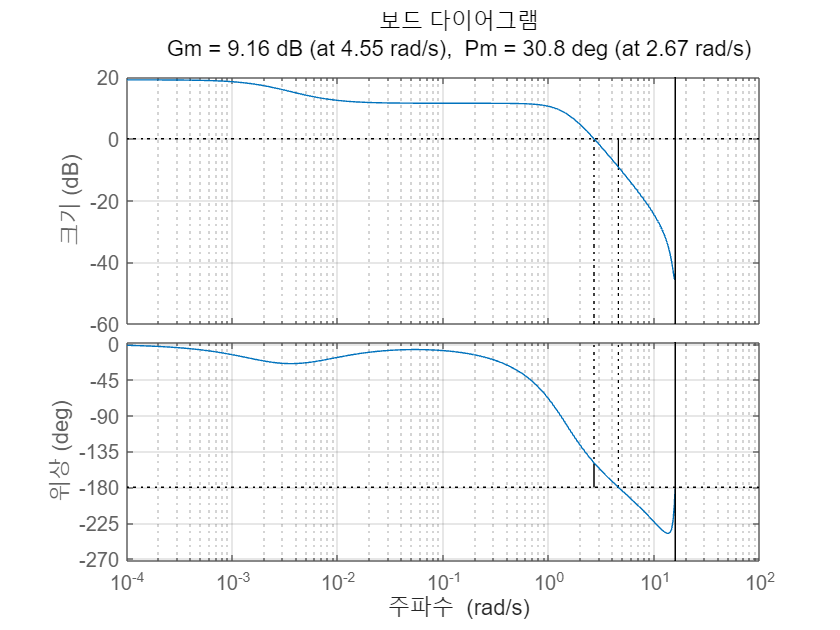

Dd_lag_tf = c2d(Dw_lag_tf, T, 'tustin');
figure();
margin(Gd_tf * Dd_lag_tf); grid on;

전체 폐루프 전달함수의 보데 선도는 다음과 같습니다. 

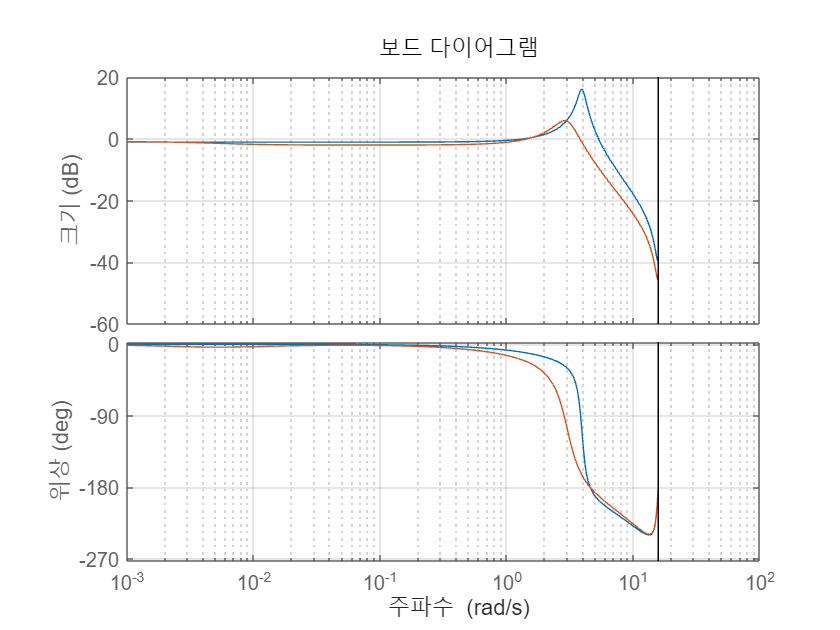

Td_tf = Gd_tf/(1 + Gd_tf);
Td_tf = minreal(Td_tf);

Td_lag_tf = Gd_tf * Dd_lag_tf/(1 + Gd_tf * Dd_lag_tf);
Td_lag_tf = minreal(Td_lag_tf);

figure();
bode(Td_tf);
hold on;
bode(Td_lag_tf);
grid on;

아래에서는 step 함수를 이용하여 두 경우에 대한 단위 계단 응답을 그렸습니다. 

위상 뒤짐 보상기는 추가적인 위상 여유를 보장해주지만, tradeoff로써 정상상태값으로의 수렴 속도가 현저히 줄어든 것을 확인할 수 있습니다.

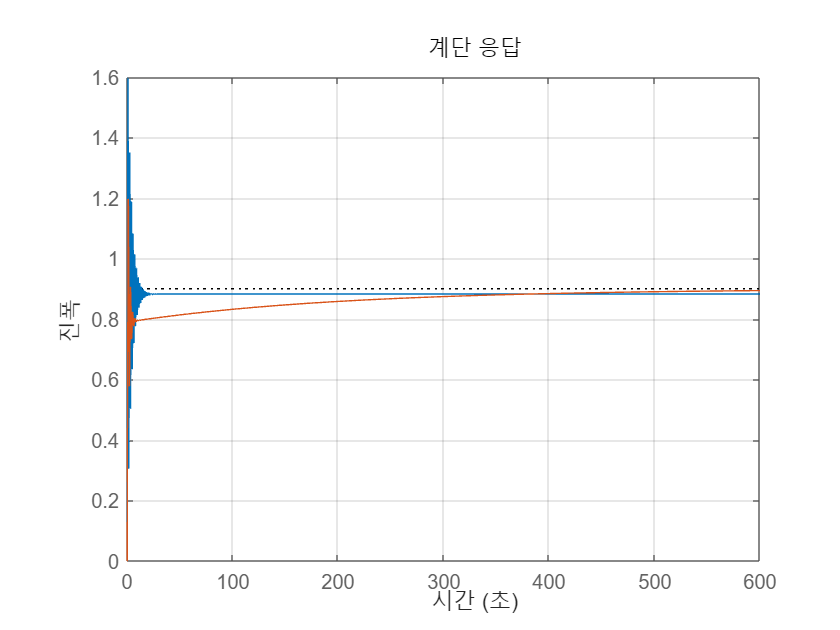

figure();
step(Td_tf);
hold on;
step(Td_lag_tf);
grid on;
xlim([0 600]);